# Digitale Logik und Schleifen mit Bedingungen ("while")

## Einführung und Lernziele

Im letzten Kapitel haben wir uns mit Programmverzweigungen beschäftigt. Abhängig davon, dass eine Bedingung erfüllt oder nicht erfüllt wird, werden bestimmte Code-Teile ausgeführt oder eben auch nicht. In der Realität hängen Entscheidungen aber oft nicht nur von einer Bedingung ab. Beispielsweise entscheide ich mich dafür, Joggen zu gehen, wenn es nicht regnet und wenn mein Laufpartner Zeit hat. Bedingungen können also miteinander kombiniert werden. Manchmal werden Handlungen auch wiederholt ausgeführt, bis eine Bedingung erfüllt ist. Ich könnte beispielsweise am verabredeten Ort auf meinen Laufpartner warten und solange jede Minute auf die Uhr sehen, bis er oder sie endlich eintrifft. 

In diesem MATLAB Live Skript beschäftigen wir uns zuerst damit, wie **kombinierte Bedingungen** in der Programmiersprache MATLAB formuliert werden. In der Informatik bezeichnet man dieses Themenfeld auch als **digitale Logik** oder **boolesche Algebra**. Anschließend lernen wir eine neue Kontrollstruktur kennen, die sogenannten **Schleifen mit Bedingungen** – Stichwort **while-Schleife**.

## Digitale Logik: und, oder, nicht

In der letzten Vorlesung haben wir den boolschen Datentyp kennengelernt: wahr oder falsch. Man kann solche Ausdrücke auch kombinieren, z.B. könnte man fordern, dass zwei Bedingungen gleichzeitg erfüllt sein sollen. 

Beispiel beim Busfahren: Kinder unter 6 Jahren können kostenlos Bus fahren. Ab 6 Jahren braucht man eine Fahrkarte. Bis 14 Jahre zahlt man den Kinderpreis, ab 15 Jahren den Erwachsenenpreis: 

alter = 12;
if (6 <= alter) && (alter <= 14)
    disp('Du musst eine Kinderfahrkarte kaufen.');
end

Im Folgenden beschäftigen wir uns daher mit der Verknüpfung von booleschen Ausdrücken. Dieses Fachgebiet nennt man auch **boolsche Algebra** oder **digitale Logik**. Wikipedia fasst hier die wichtigsten Regeln zur booleschen Algebra zusammen: [https://de.wikipedia.org/wiki/Boolesche_Algebra](https://de.wikipedia.org/wiki/Boolesche_Algebra) 

Wir werden in dieser Vorlesung uns aber auf die logischen Verknüpfungen oder logischen Operatoren 

- UND

- ODER

- NICHT

beschränken. 

### Das logische UND

Beim logischen UND müssen beide Bedingungen erfüllt sein, damit insgesamt die kombinierte Bedingung erfüllt ist. Vergleichbar ist dies mit einer Reihenschaltung in der Elektrotechnik. Nur wenn beide Schalter eingeschaltet sind, kann der Strom fließen. 

Hier finden Sie den Link zu einem YouTube-Video (ca. 3:14 min) von Lehrer Schmidt zur UND-Schaltung:

[https://www.youtube.com/watch?v=79WVEr2BVZI](https://www.youtube.com/watch?v=79WVEr2BVZI)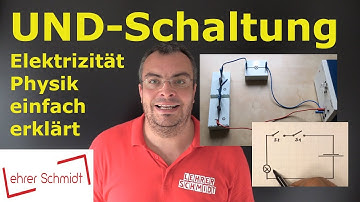

Man schreibt die Ergebnisse der kombinierten Bedingungen normalerweise als eine Tabelle auf. Die erste Zeile würde man so lesen: Wenn "Bedingung 1 wahr" ist UND wenn "Bedingung 2 wahr" ist, so ist auch die kombinierte Bedingung "Bedingung 1 UND Bedingung 2" wahr. Wir verwenden hier schon die MATLAB-Werte `true` für wahr und `false` für falsch.

`Bedingung 1 | Bedingung 2 | Bedingung 1 UND Bedingung 2`

`------------|-------------|----------------------------`

`true        | true        | true`

`false       | true        | false`

`true        | false       | false`

`false       | false       | false`

In MATLAB wird die Kombination oder die sogeannte Verknüpfung zweier Bedingungen mit dem &&-Operator umgesetzt. Dabei wird das Symbol `& `kaufmännisches Und-Zeichen oder Et-Zeichen genannt. Auf einer deutschen Tastatur liegt das kaufmännische Und-Zeichen auf der oberen Tastenreihe über der Ziffer 6.

Beispiel: Zwei Personen wollen einen Kinofilm sehen, der erst ab 18 erlaubt ist. Nur wenn beide volljährig sind, können sie den Film gemeinsam besuchen:

alter_person1 = 19;
alter_person2 = 22;
if (alter_person1 >= 18) && (alter_person2 >= 18)
    disp('Sie duerfen beide den Film sehen.');
else
    disp('Vielleicht darf einer von Ihnen den Film sehen, aber nicht beide.');
end

#### Mini-Übung 1

Schreiben Sie ein Skript, das nach dem Alter einer Person fragt. Wenn das Alter der Person zwischen 6 und 10 liegt, soll das Programm ausgeben "Wahrscheinlich gehst Du in die Grundschule."

% Hier Ihr Code


#### Mini-Übung 2

Schreiben Sie ein Skript und lassen Sie den MATLAB-Interpreter nach einem Monat fragen. Dabei soll für den Januar eine 1 eingegeben werden, für den Februar eine 2 usw. Danch soll der MATLAB-Interpreter folgendes ausgeben:

- für Monate März, April, Mai: Frühling

- für Monate Juni, Juli, August: Sommer

- für Monate September, Oktober, November: Herbst

- für Monate Dezember, Januar, Februar: Winter 

% Hier Ihr Code


#### Mini-Übung 3

Schreiben Sie ein Skript, das nach dem Alter einer Person fragt. Wenn die Person 0 bis 17 ist, soll das Programm ausgeben: "Wahrscheinlich bist Du noch nicht berufstätig". Zwischen 18 und 67 soll ausgegeben werden "Wahrscheinlich sind Sie berufstätig." und bei Personen zwischen 68 und 120 "Wahrscheinlich sind Sie nicht mehr berufstätig."

% Hier Ihr Code


### Das logische ODER

Beim logischen ODER muss nur eine der beiden Bedingungen erfüllt sein, damit insgesamt die kombinierte Bedingung erfüllt ist. Damit ist natürlich die Bedingung insgesamt auch erfüllt, wenn beide Bedingungen wahr sind. Vergleichbar ist dies mit einer Parallelschaltung in der Elektrotechnik. Es reicht, wenn einer der beiden Schalter eingeschaltet sind, damit der Strom fließen kann. Auch wenn beide Schalter eingeschaltet sind, fließt Strom. 

Hier finden Sie den Link zu einem YouTube-Video (ca. 2:42 min) von Lehrer Schmidt zur ODER-Schaltung:

[https://www.youtube.com/watch?v=UNkXbvSN9w8](https://www.youtube.com/watch?v=UNkXbvSN9w8)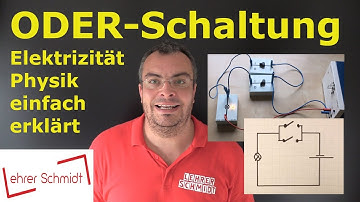

Auch bei der ODER-Verknüpfung schreibt man üblicherweise die Ergebnisse der kombinierten Bedingungen in Form einer Tabelle. Die dritte Zeile würde man beispielsweise so lesen: Wenn "Bedingung 1 wahr" ist ODER wenn "Bedingung 2 falsch" ist, so ist auch die kombinierte Bedingung "Bedingung 1 ODER Bedingung 2" wahr. Wir verwenden hier wiederum die MATLAB-Werte `true` für wahr und `false` für falsch.

`Bedingung 1 | Bedingung 2 | Bedingung 1 ODER Bedingung 2`

`------------|-------------|-----------------------------`

`true        | true        | true`

`false       | true        | true`

`true        | false       | true`

`false       | false       | false`

In MATLAB wird dies mit dem `||`-Operator umgesetzt. Der senkrechte Strich findet sich auf einer deutschen Tastatur auf der Taste mit den spitzen Klammern < > und wird gesetzt, indem man die Alt Gr Taste gleichzeitig drückt.

Beispiel: Zwei Personen wollen ein Auto mieten, dazu muss aber mindestens einer von den beiden den Führerschein besitzen.

person1_hat_fuehrerschein = true;
person2_hat_fuehrerschein = false;

if (person1_hat_fuehrerschein == true) || (person2_hat_fuehrerschein == true)
    disp('Sie duerfen das Auto mieten.')
else
    disp('Keiner von beiden hat einen Fuehrerschein, geht nicht.')
end

#### Mini-Übung 4

Schreiben Sie ein Skript, das nach dem Alter einer Person fragt. Wenn die Person jünger als 18 ist oder älter als 67, soll das Programm ausgeben: "Wahrscheinlich sind Sie/bist Du nicht berufstätig."

% Hier Ihr Code


#### Mini-Übung 5

Schreiben Sie ein Skript, das nach der Länge der beiden Seiten eines rechtwinkligen Dreiecks fragt, die am rechten Winkel anliegen (= Katheten). Wenn eine der beiden Seitenlängen oder beide negativ sind, soll das Programm ausgeben: "Fehler, negative Seitenlängen gibt es nicht!" und ansonsten soll das Skript die Länge der dritten Seite (= Hypotenuse) mit der Formel (= Satz des Pythagoras) $c = \sqrt{a^2 + b^2}$ berechnen und das Ergebnis ausgeben.

% Hier Ihr Code


### Das logische NICHT

Das logische NICHT kehrt eine Aussage um. Wenn eine Bedingung wahr war, wird sie falsch. War jedoch die Bedingung vorher wahr, wird sie nach Anwendung des logischen NICHT falsch. Man auch diese Operation normalerweise als Tabelle auf:

`Bedingung 1 | NICHT Bedingung 1`

`------------|-----------------------`

`true        | false`

`false       | true        `

In MATLAB wird dies mit dem `~` -Operator umgesetzt. Das Zeichen `~` wird Tilde genannt. Die Tilde finden Sie auf einer deutschen Tastatur zwischen der Ü-Taste und der Return-Taste auf der Taste mit + und *. Um das Tilde-Zeichen einzugeben, müssen Sie gleichzeitig die Alt Gr-Taste drücken.

Beispiel: Wenn eine Person keinen Führerschein hat, muss sie den Bus nehmen.

person_hat_fuehrerschein = false;

if ~person_hat_fuehrerschein
    disp('Sie muessen Bus fahren.');
else
    disp('Sie duerfen Auto fahren.');
end

#### Mini-Übung 6

Überlegen Sie zunächst, was ist das Ergebnis der folgenden Verknüpfungen: wahr oder falsch?

- wahr UND wahr

- wahr ODER falsch

- NICHT wahr

- falsch ODER wahr

- wahr ODER (NICHT falsch)

- (NICHT wahr) UND falsch

- NICHT (wahr ODER falsch)

- (NICHT falsch) ODER (falsch UND falsch)

Probieren Sie dann in der nächsten Code-Zelle aus, ob Sie die richtigen Ergebnisse hatten, indem Sie beispielsweise wahr und wahr in MATLAB ausprobieren, also beispielsweise 

eingeben:

% Hier Ihr Code:


## Schleifen: Wiederholung mit Bedingung "while"

Bei einer Wiederholung mit Bedingung wird eine Anweisung solange wiederholt, bis die Bedingung erfüllt wird. Sie hat folgende Struktur:

`while Bedingung`

`    anweisungsblock`

`end`

Die bedingte Wiederholung wird mit dem Schlüsselwort `while` eingeleitet. Dann folgt die Bedingung. Alle Anweisungen, die wiederholt werden sollen, kommen nach der Bedingung. Diesen Teil nennt man das Schleifeninnere, die Zeile "while Bedingung" nennt man den Schleifenkopf. 

Beispiel: Wir möchten ein Programm schreiben, bei dem der Benutzer solange Zahlen eingeben darf, die quadriert werden, bis die Null eingegeben wird. Dies würde in MATLAB wie folgt umgesetzt:

disp('Dieses Programm quadriert ganze Zahlen solange, ');
disp('bis Sie die 0 eingeben.');
zahl = input('Bitte geben Sie die 1. Zahl ein: ');

while zahl ~= 0
    disp(zahl^2);
    zahl = input('Bitte geben Sie eine weitere Zahl ein (0 für Ende): ');
end
disp('Sie haben die 0 eingegeben. Hiermit wird das Programm beendet.')

Ein anderes Beispiel, das oft in der Programmierung vorkommt ist, dass eine Variable gezählt wird. Dafür werden wir in einer späteren Vorlesung noch eine Alternative kennenlernen. Hier ein Beispiel, bei der eine Variable "hochgezählt" wird:

zaehler = 1;
while zaehler <= 10
    disp(zaehler);
    zaehler = zaehler + 1;
end

#### Mini-Übung 7

Schreiben Sie ein Skript, das die Quadratzahlen für 10 bis 20 ausgibt, d.h. es sollen die Zahlen 100, 121, ... , 400 ausgegeben werden.

% Hier Ihr Code:


#### Mini-Übung 8

Schreiben Sie ein Skript, das einen Benutzer oder eine Benutzerin auffordert, eine positive Zahl einzugeben. Falls dabei jedoch fälschlicherweise eine negative Zahl oder die Null eingegeben wird, soll der Computer solange weiter fragen, bis endlich eine positive Zahl eingegeben wird.

% Hier Ihr Code


## Zusammenfassung

In diesem MATLAB Live Skript haben wir uns eingehend mit der Kombination von Bedingungen beschäftigt, um zukünftig realistischere Alltagsszenarien auch in Code umsetzen zu können. Dabei haben wir die drei wichtigsten Verknüpfungen der digitalen Logik kennengelernt: UND, ODER und NICHT. In den nächsten MATLAB Live Skripten werden wir die kombinierten Bedingungen nicht nur für Programmverzweigungen, sondern auch für wiederholte Ausführungen von Code-Abschnitten einsetzen. Dazu haben wir in diesem Skript die while-Schleife eingeführt, die Code solange wiederholt, wie die Bedingung im Schleifenkopf erfüllt ist. Auch das Thema Schleifen werden wir im nächsten MATLAB Live Skript weiter vertiefen und als Alternative für eine while-Schleife mit einer Zählbedingung die sogenannte for-Schleife kennenlernen. 

## Lösungen zu den Mini-Übungen

**Lösung zu Mini-Übung 1**

Schreiben Sie ein Skript, das nach dem Alter einer Person fragt. Wenn das Alter der Person zwischen 6 und 10 liegt, soll das Programm ausgeben "Wahrscheinlich gehst Du in die Grundschule."

% Eingabe
alter = input('Wie alt sind Sie?');

% Verarbeitung und Ausgabe
if (6 <= alter) && (alter <= 10)
    disp('Wahrscheinlich gehst Du in die Gundschule.');
end

**Lösung zu Mini-Übung 2**

Schreiben Sie ein Skript und lassen Sie den MATLAB-Interpreter nach einem Monat fragen. Dabei soll für den Januar eine 1 eingegeben werden, für den Februar eine 2 usw. Danch soll der MATLAB-Interpreter folgendes ausgeben:

- für Monate März, April, Mai: Frühling

- für Monate Juni, Juli, August: Sommer

- für Monate September, Oktober, November: Herbst

- für Monate Dezember, Januar, Februar: Winter 

% Eingabe
monat = input('Geben Sie den aktuellen Monat ein, 1 für Januar, 2 für Februar, usw.')

% Verarbeitung und Ausgabe
if 3 <= monat && monat <= 5
    disp('Frühling');
elseif 6 <= monat && monat <= 8
    disp('Sommer');
elseif 9 <= monat && monat <= 11
    disp('Herbst');
else
    disp('Winter');
end

**Lösung zu Mini-Übung 3**

Schreiben Sie ein Skript, das nach dem Alter einer Person fragt. Wenn die Person 0 bis 17 ist, soll das Programm ausgeben: "Wahrscheinlich bist Du noch nicht berufstätig". Zwischen 18 und 67 soll ausgegeben werden "Wahrscheinlich sind Sie berufstätig." und bei Personen zwischen 68 und 120 "Wahrscheinlich sind Sie nicht mehr berufstätig."

% Eingabe
alter =  input('Alter: ');

% Verarbeitung und Ausgabe
if (0 <= alter) && (alter <= 17)
    disp('Wahrscheinlich bist Du noch nicht berufstätig.');
end
if (18 <= alter) && (alter <= 67)
    disp('Wahrscheinlich sind Sie berufstätig.');
end
if (68 <= alter) && (alter <= 120)
    disp('Wahrscheinlich sind Sie nicht mehr berufstätig.');
end

**Lösung zu Mini-Übung 4**

Schreiben Sie ein Skript, das nach dem Alter einer Person fragt. Wenn die Person jünger als 18 ist oder älter als 67, soll das Programm ausgeben: "Wahrscheinlich sind Sie/bist Du nicht berufstätig."

% Eingabe
alter =  input('Alter: ');

% verarbeitung und Ausgabe
if (alter < 18) || (67 < alter)
    disp('Wahrscheinlich sind Sie/bist Du nicht berufstätig.');
end

**Lösung zu Mini-Übung 5**

Schreiben Sie ein Skript, das nach der Länge der beiden Seiten eines rechtwinkligen Dreiecks fragt, die am rechten Winkel anliegen (= Katheten). Wenn eine der beiden Seitenlängen oder beide negativ sind, soll das Programm ausgeben: "Fehler, negative Seitenlängen gibt es nicht!" und ansonsten soll das Skript die Länge der dritten Seite (= Hypotenuse) mit der Formel (= Satz des Pythagoras) $c = \sqrt{a^2 + b^2}$ berechnen und das Ergebnis ausgeben.

% Eingabe 
disp('Bitte geben Sie die Längen der Katheten eines rechtwinkligen Dreiecks ein:');
a = input('Länge Seite a: ');
b = input('Länge Seite b: ');
if (a<0) || (b<0)
    disp('Fehler, negative Seitenlängen gibt es nicht!');
else
    disp('Die Länge der Seite c (= Hypotenuse) ist: ');
    disp(sqrt(a^2+b^2));
end

**Lösung zu Mini-Übung 6**

Überlegen Sie zunächst, was ist das Ergebnis der folgenden Verknüpfungen: wahr oder falsch?

- wahr UND wahr

- wahr ODER falsch

- NICHT wahr

- falsch ODER wahr

- wahr ODER (NICHT falsch)

- (NICHT wahr) UND falsch

- NICHT (wahr ODER falsch)

- (NICHT falsch) ODER (falsch UND falsch)

Probieren Sie dann in der nächsten Code-Zelle aus, ob Sie die richtigen Ergebnisse hatten, indem Sie beispielsweise wahr und wahr in MATLAB ausprobieren, also beispielsweise 

eingeben:

Anmerkung: Der MATLAB-Interpreter merkt, dass ein Vergleich wie beispielsweise` false && false` nicht komplett überprüft werden muss, da bereits das erste` false` dazu führt, dass das Ergebnis der Verknüpfung falsch ist. Daher wird hier in der Code-Zelle eine Warnung angezeigt. Um diese Warnungen im Skript zu vermeiden, ist der Code hier als Code Example und nicht in einer Code-Zelle eingefügt.

**Lösung zu Mini-Übung 7**

Schreiben Sie ein Skript, das die Quadratzahlen für 10 bis 20 ausgibt, d.h. es sollen die Zahlen 100, 121, ... , 400 ausgegeben werden.

% Eingabe Startzahl
zahl = 10;

% Verarbeitung und Ausgabe
while zahl <= 20
    disp(zahl^2);
    zahl = zahl + 1;
end

**Lösung zu Mini-Übung 8**

Schreiben Sie ein Skript, das einen Benutzer oder eine Benutzerin auffordert, eine positive Zahl einzugeben. Falls dabei jedoch fälschlicherweise eine negative Zahl oder die Null eingegeben wird, soll der Computer solange weiter fragen, bis endlich eine positive Zahl eingegeben wird.

% Eingabe
x = input('Bitte geben Sie eine positive ganze Zahl ein: ');

% Fehlerbehandlung: Verarbeitung und Ausgabe
while x <= 0
    x = input('Bitte geben Sie eine POSITIVE ganze Zahl ein: ')
end